clear
close all
clc

    One needs to run the previous code first, which is "task1.mlx", to get the transfer function in between '/phi_0' and '/phi' (true roll angle) , and then continue with the procedure here!

Y_v_nom = -0.1068;       % [1/s]         -> 4.26 %
Y_p_nom = 0;             % [m/(s rad)]   -> -
L_v_nom = 0;             % [rad s/m]     -> 1.83 %
L_p_nom = -2.6478;       % [1/s]         -> 2.01

Y_d_nom = -10.1647;      % [m/s^2]       -> 1.37 %
L_d_nom = 450.7085;      % [rad/s^2]     -> 0.81 %

unc_Y_v = 3*4.26;
unc_L_p = 3*2.01;
unc_Y_d = 3*1.37;
unc_L_d = 3*0.81;

% Stability Derivatives
Y_v = ureal('Y_v',Y_v_nom,'Perc',unc_Y_v);
Y_p = Y_p_nom;
L_v = L_v_nom;
L_p = ureal('L_p',L_p_nom,'Perc',unc_L_p);

% Control Derivatives
Y_d = ureal('Y_d',Y_d_nom,'Perc',unc_Y_d);
L_d = ureal('L_d',L_d_nom,'Perc',unc_L_d);

The new state-space matrices for second task should be created using the derivatives above

g = 9.81;   % Gravity Constant
Ts = 0.01;  % Sampling Time

% State Space Model for Position Control
A = [L_p L_v 0; Y_p Y_v 0; 0 1 0];
B = [0 g 0]';
C = [0 1 0; 0 0 1];
D = [0 0]';

% Uncertain Plant
sys_ld = ss(A,B,C,D)

sys_ld =

  Uncertain continuous-time state-space model with 2 outputs, 1 inputs, 3 states.
  The model uncertainty consists of the following blocks:
    L_p: Uncertain real, nominal = -2.65, variability = [-6.03,6.03]%, 1 occurrences
    Y_v: Uncertain real, nominal = -0.107, variability = [-12.8,12.8]%, 1 occurrences

Type "sys_ld.NominalValue" to see the nominal value, "get(sys_ld)" to see all properties, and "sys_ld.Uncertainty" to interact with the uncertain elements.



sys_ld.u = '\phi';
sys_ld.y = {'v','y'};
sys_ld_d = c2d(tf(sys_ld),Ts,'tastin');

% Nominal Plant
sys_ld_nom = sys_ld.NominalValue

sys_ld_nom =
 
  A = 
            x1       x2       x3
   x1   -2.648        0        0
   x2        0  -0.1068        0
   x3        0        1        0
 
  B = 
       \phi
   x1     0
   x2  9.81
   x3     0
 
  C = 
      x1  x2  x3
   v   0   1   0
   y   0   0   1
 
  D = 
      \phi
   v     0
   y     0
 
Continuous-time state-space model.



sys_ld_nom.u = '\phi';
sys_ld_nom.y = {'v','y'};
sys_ld_nom_d = c2d(tf(sys_ld_nom),Ts,'tastin');

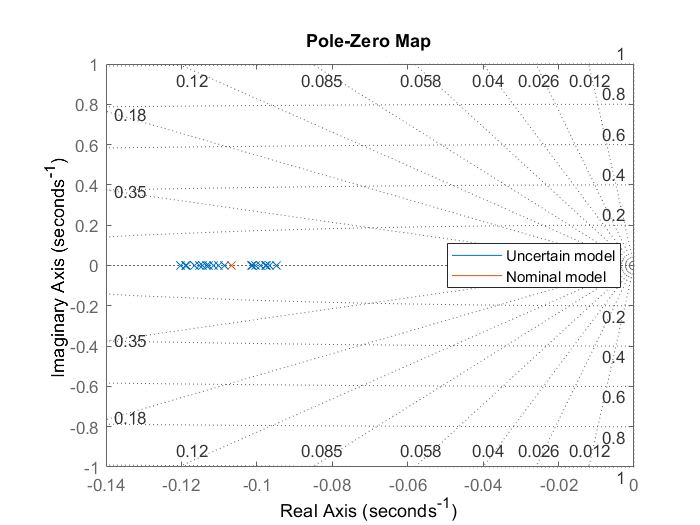

G_phi_v_nom = tf(sys_ld_nom(1));

figure
pzplot(sys_ld(1));
hold on
pzplot(sys_ld_nom(1));
grid on
legend('Uncertain model','Nominal model','location','east')


z_phi_v = tzero(sys_ld_nom(1))

z_phi_v =          0
   -2.6478


p_phi_v = pole(sys_ld_nom(1))

p_phi_v =    -0.1068
   -2.6478
         0


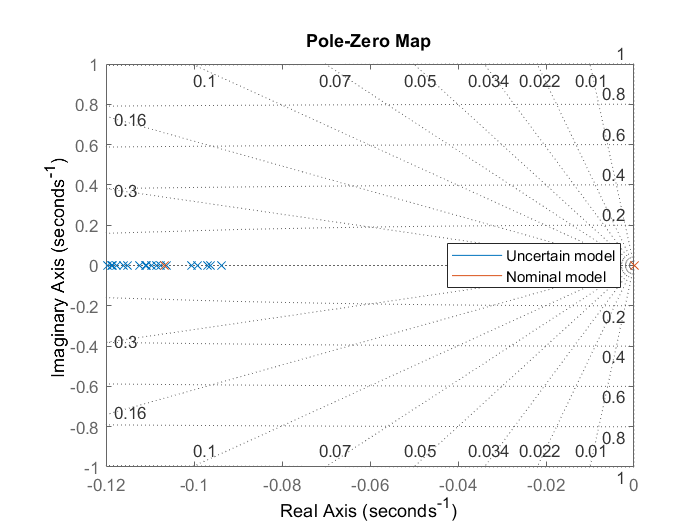

G_phi_y_nom = tf(sys_ld_nom(2));

figure
pzplot(sys_ld(2));
hold on
pzplot(sys_ld_nom(2));
grid on
legend('Uncertain model','Nominal model','location','east')


z_phi_y = tzero(sys_ld_nom(2))

z_phi_y = -2.6478

p_phi_y = pole(sys_ld_nom(2))

p_phi_y =          0
   -0.1068
   -2.6478


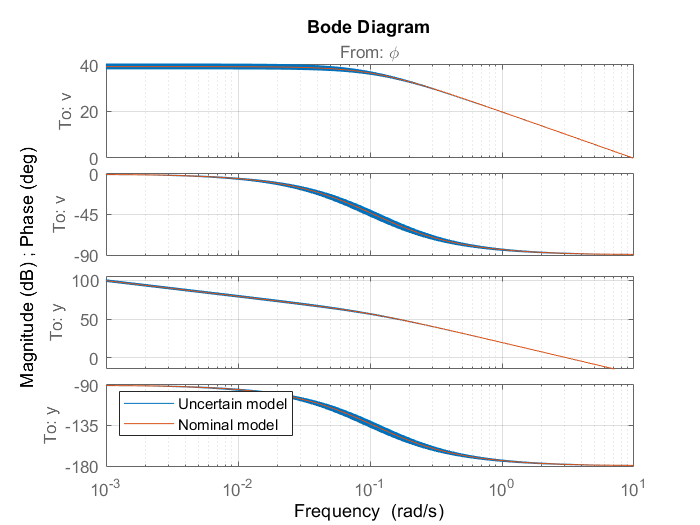

figure
bode(sys_ld)
hold on
bode(sys_ld_nom)
grid on
legend('Uncertain model','Nominal model','location','northwest')

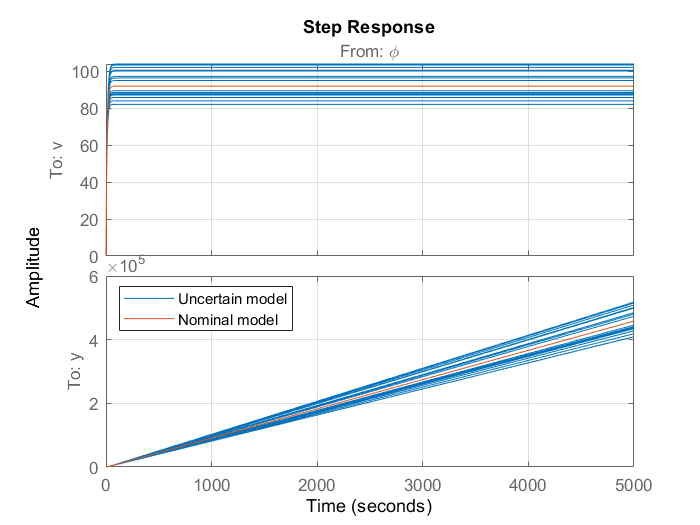

figure
step(sys_ld)
hold on
step(sys_ld_nom)
grid on
legend('Uncertain model','Nominal model','location','northwest')

R_y = tunablePID('R_y','P',Ts);
R_y.u = 'e_y';
R_y.y = 'v_0';

R_v = tunablePID2('R_v','PID',Ts);
R_v.c.Value = 0;
R_v.c.Free = false;
R_v.b.Value = 1;
R_v.b.Free = false;
R_v.Tf.Value = 0.01;
R_v.Tf.Free = false;
R_v.u = {'v_0','v'};
R_v.y = {'\phi_0'};

SumOuter = sumblk('e_y = y_0 - y');

load("F_phi_tf.mat");
F_phi_tf.u = {'\phi_0'};
F_phi_tf.y = {'\phi'};
F_phi_tf_d = c2d(F_phi_tf,Ts,'tastin');

CL_tun = connect(SumOuter,R_y,R_v,F_phi_tf_d,sys_ld_nom_d,'y_0',{'y','v'});

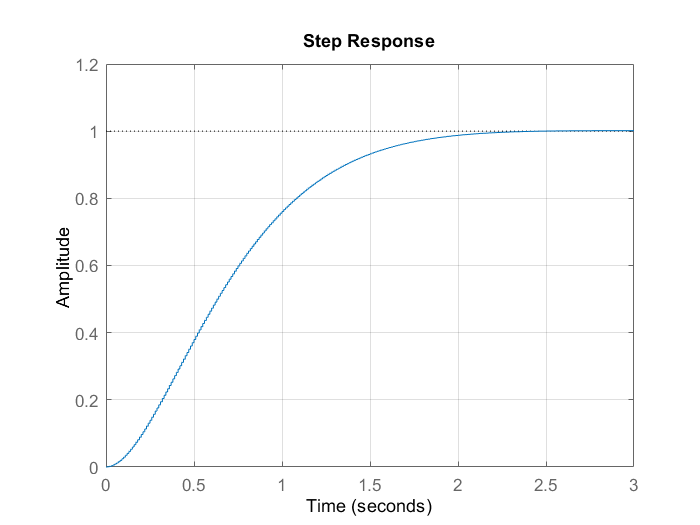

omega_n = 2.5;       % [rad/s]
xi = 0.9;

s = tf('s');

F_2 = omega_n^2/(s^2 + 2*s*xi*omega_n + omega_n^2);
F_2_d = c2d(F_2,Ts,'tastin');
S_2 = 1-F_2;
S_2_d = c2d(S_2,Ts,'tastin');

figure
step(F_2_d)
grid on


stepinfo(F_2_d)

ans = struct with fields:
        RiseTime: 1.1500
    SettlingTime: 1.8800
     SettlingMin: 0.9007
     SettlingMax: 1.0015
       Overshoot: 0.1525
      Undershoot: 0
            Peak: 1.0015
        PeakTime: 2.8800


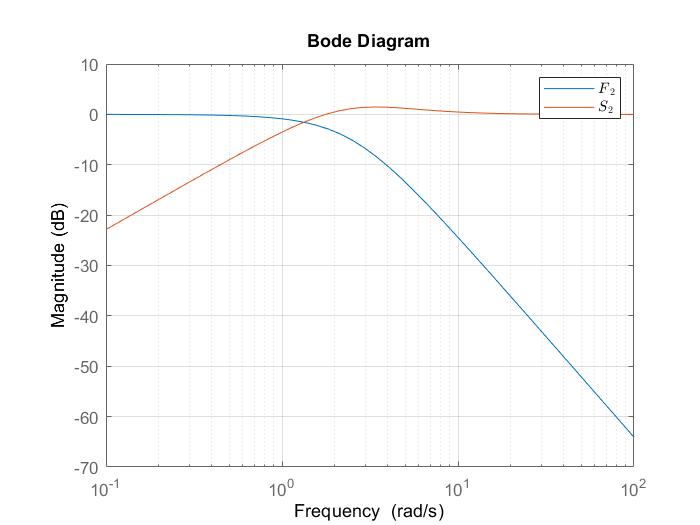

figure
bodemag(F_2)
hold on
bodemag(S_2)
grid on
legend('$F\_2$','$S\_2$','interpreter','latex')


$$W_p(s) = \frac{\frac{s}{M} + \omega_b}{s + A \omega_b}$$


The objective is that $1/W_p(s)$ is used to shape our sensitivity function in order to have $S(s) \simeq S_2(s)$.

Where $M$ is related to the peak, $A$ is related to the value at steady state and $\omega_b$ is related to the cross-over frequency and so to the settling time of our response.

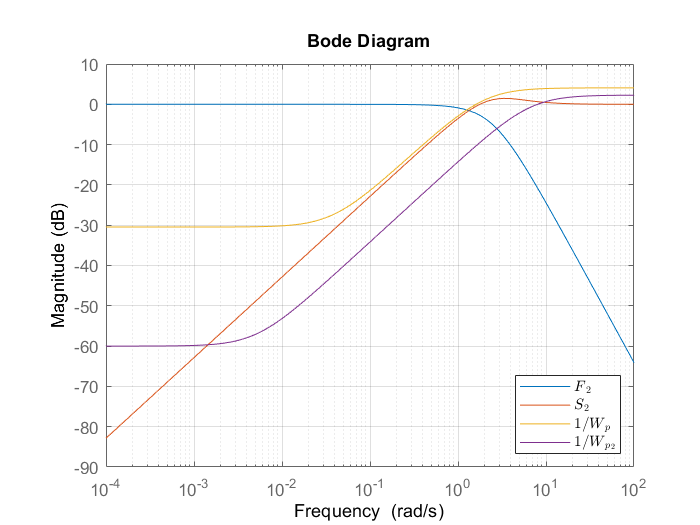

M =1.6;
A = 3e-2;
omega_b = 0.5*omega_n;

W_p = (s/M + omega_b)/(s + A*omega_b);
W_p2inv = makeweight(1e-3,8,1.3,0,1);
W_p2 = 1/W_p2inv;

W_p_d = c2d(W_p, 0.01,'tastin');
W_p2inv_d = c2d(W_p2inv, 0.01,'tastin');
W_p2_d = c2d(W_p2, 0.01,'tastin');

figure
bodemag(F_2)
hold on
bodemag(S_2)
grid on
bodemag(1/W_p)
bodemag(1/W_p2)
legend('$F\_2$','$S\_2$','$1/W\_p$','$1/W\_{p\_{2}}$','interpreter','latex', 'location','southeast')

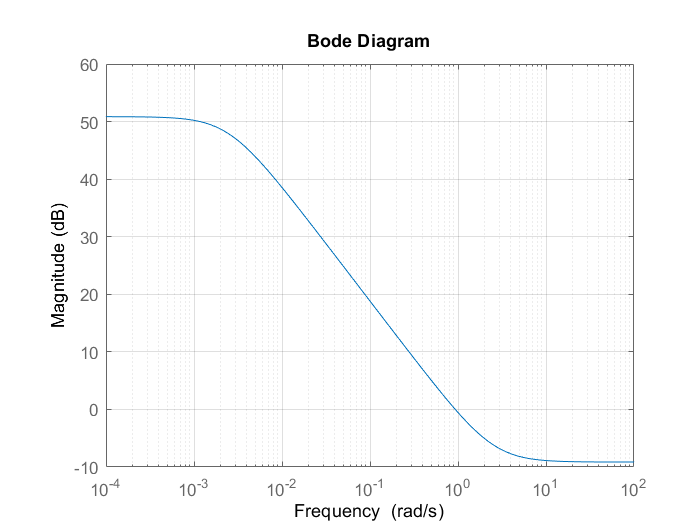

alpha = 2/deg2rad(40);
w_tau = 2.5;

W_q = alpha*(s+w_tau*1e-3)/(s+w_tau);

figure
bodemag(1/W_q)
grid on

W_p.u = 'e_y';
W_p.y = 'z_1';

W_q.u = '\phi';
W_q.y = 'z_2';

W_p_d = c2d(tf(W_p),Ts,'tastin');
W_q_d = c2d(tf(W_q),Ts,'tastin');

%We have to define our new closed-loop to include also the weights defined. For simplicity we have added three
% additional analysis points that will be useful to compute sensitivities of the tuned closed-loop

CL0 = connect(R_v, R_y, F_phi_tf_d, sys_ld_nom_d, SumOuter, W_p_d, W_q_d,...
    'y_0',{'z_1','z_2'},{'\phi','e_y','y'});

opt = hinfstructOptions('Display','final','RandomStart',10)

opt =   hinfstruct with properties:

         Display: 'final'
         MaxIter: 300
     RandomStart: 10
     UseParallel: 0
      TargetGain: 0
         TolGain: 1.0000e-03
        MinDecay: 1.0000e-07
    MaxFrequency: Inf



[CL,gamma,info] = hinfstruct(CL0,opt);

Final: Peak gain = 1.17, Iterations = 45
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 1.17, Iterations = 48
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 1.17, Iterations = 46
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 1.16, Iterations = 39
Final: Peak gain = 1.16, Iterations = 52
Final: Peak gain = 1.16, Iterations = 44
Final: Peak gain = 1.16, Iterations = 33
Final: Peak gain = 1.17, Iterations = 32
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 1.17, Iterations = 58
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 1.17, Iterations = 57
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 1.16, Iterations = 40


showTunable(CL)

R_v =
 
                        Ts                   1     
  u = Kp (b*r-y) + Ki ------ (r-y) + Kd ----------- (c*r-y)
                        z-1             Tf+Ts/(z-1)

  with Kp = 1.7, Ki = 0.588, Kd = 0.441, Tf = 0.01, b = 1, c = 0, Ts = 0.01
 
Name: R_v
Sample time: 0.01 seconds
Discrete-time 2-DOF PIDF controller in parallel form.
-----------------------------------
R_y =
 
  Kp = 1.02
 
Name: R_y
P-only controller.


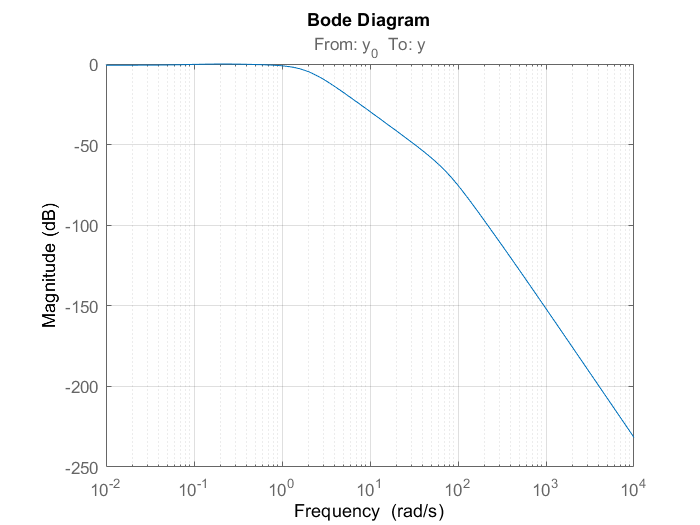

F = getIOTransfer(CL,'y_0','y');
F_c = d2c(tf(F),'tastin');

figure
bodemag(F_c)
grid on

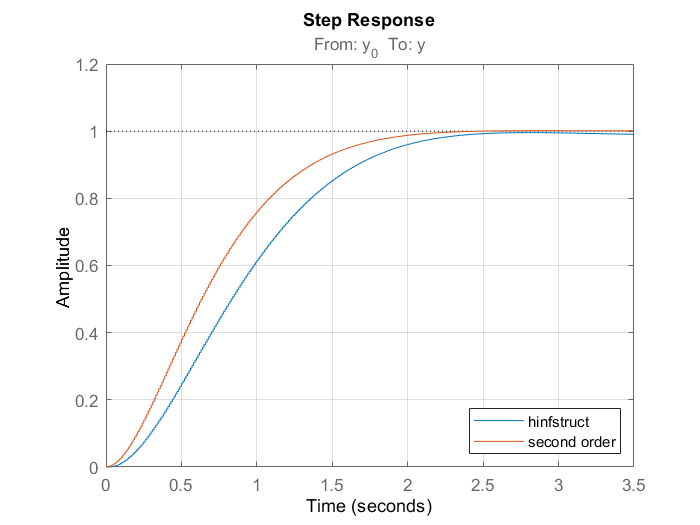

figure
step(F)
hold on
step(F_2_d)
grid on
legend('hinfstruct','second order', 'location','southeast')


stepinfo(F)

ans = struct with fields:
        RiseTime: 1.3700
    SettlingTime: 2.2100
     SettlingMin: 0.9021
     SettlingMax: 0.9957
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9957
        PeakTime: 2.8000


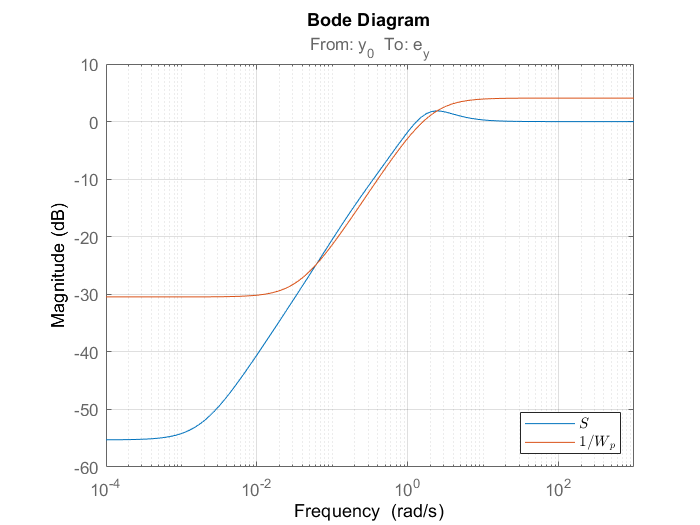

S = getIOTransfer(CL,'y_0','e_y');
S_c = d2c(tf(S),'tastin');

figure
bodemag(S_c)
grid on
hold on
bodemag(1/W_p)
legend('$S$','$1/W\_p$','interpreter','latex', 'location','southeast')

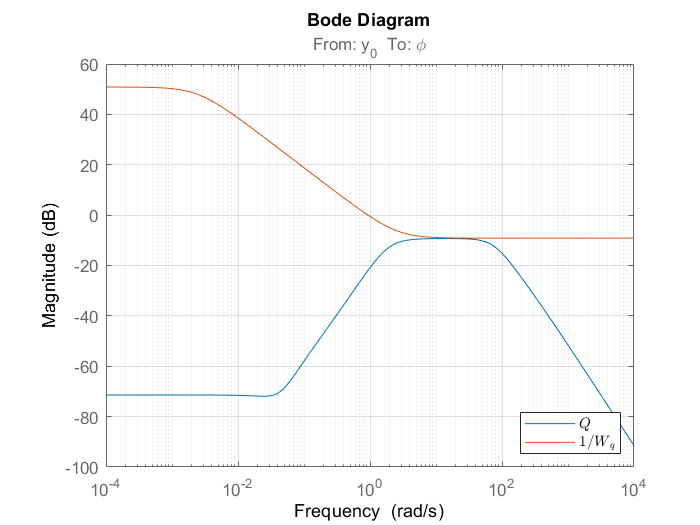

Q = getIOTransfer(CL,'y_0','\phi');
Q_c = d2c(tf(Q),'tastin');

figure
bodemag(Q_c)
grid on
hold on
bodemag(1/W_q)
legend('$Q$','$1/W\_q$','interpreter','latex', 'location','southeast')

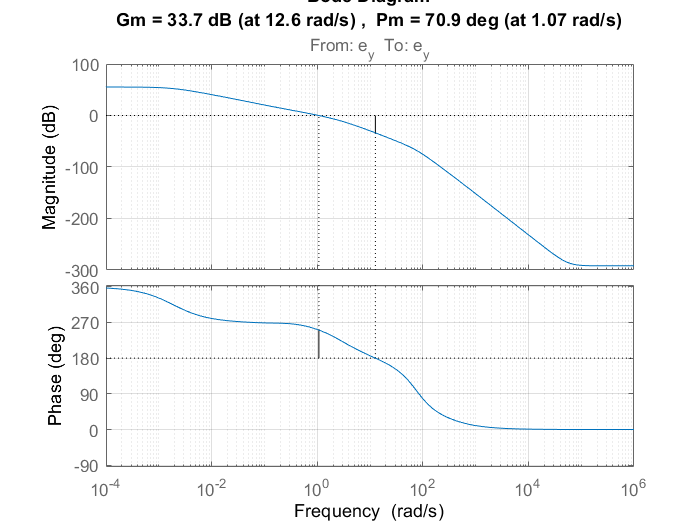

L = (1-S_c)/S_c;
%L_c = d2c(tf(L),'tastin');

figure
margin(L)
grid on

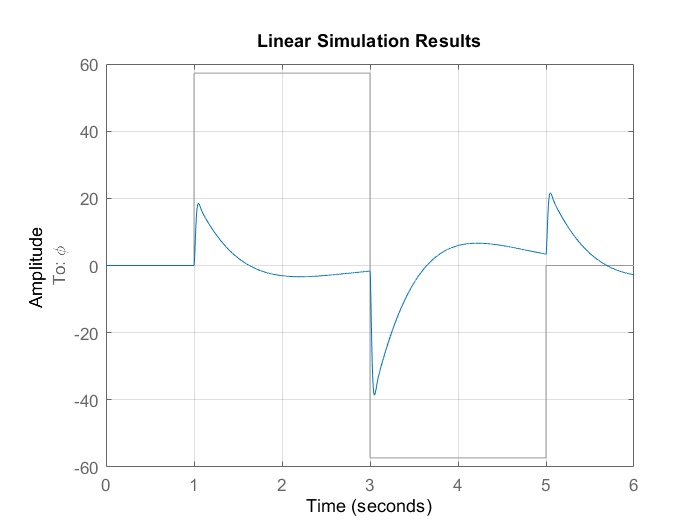

t = linspace(0,6,10^4);
u = 0*(t<=1) + 1*(t>1 & t<= 3) - 1*(t>3 & t<= 5) + 0*(t>5);
u = rad2deg(u);

figure
lsim(Q_c,u,t);
hold on
grid on

sys_ld_array = usample(sys_ld(2),60);

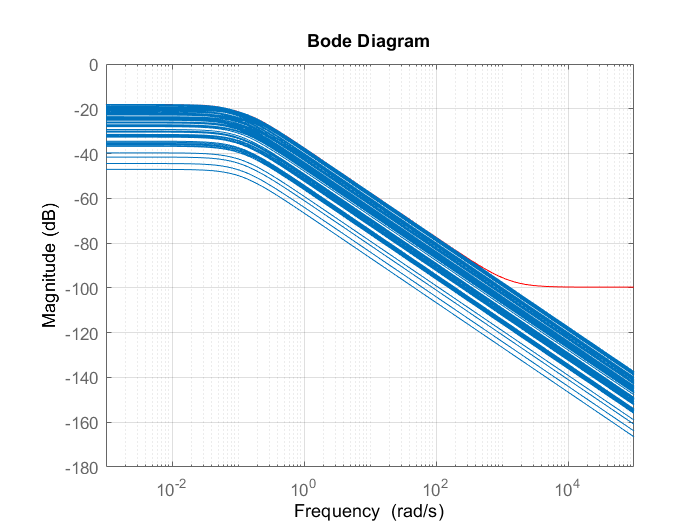

[~,Info] = ucover(sys_ld_array,sys_ld_nom(2),3);

W = Info.W1;


figure
bodemag(W,'r')
hold on
bodemag((sys_ld_nom(2)-sys_ld_array)/sys_ld_nom(2),{10e-4,10e4})
grid on

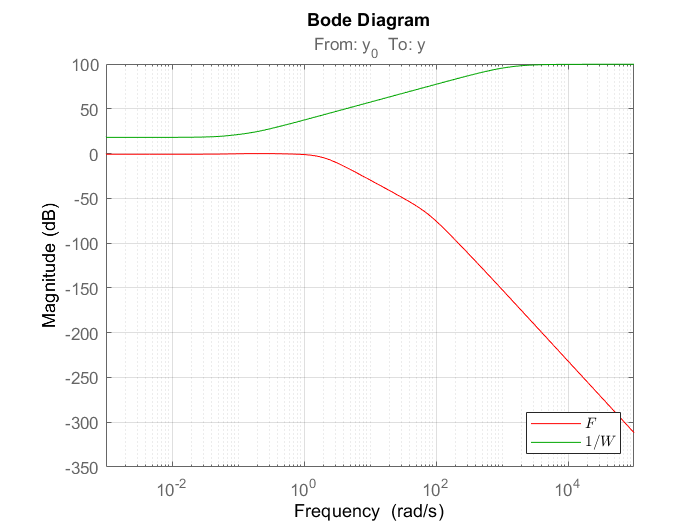

figure
bodemag(F_c,'r',1/W,'g')
grid on
legend('$F$','$1/W$','interpreter','latex', 'location','southeast')

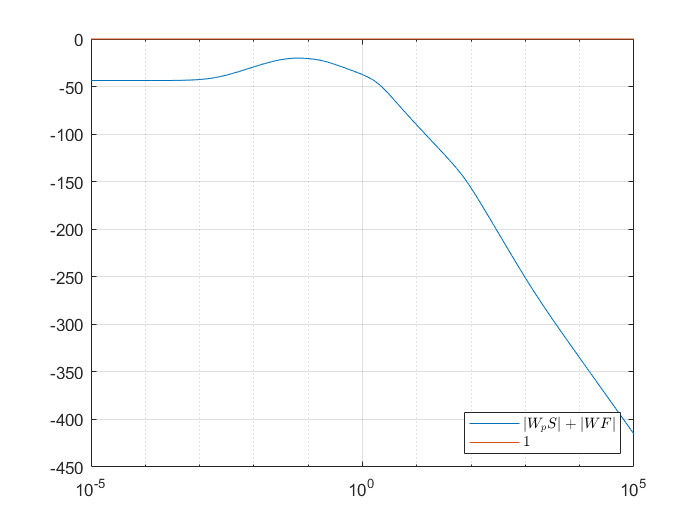

w = logspace(-5,5,500);

FW = bode(F_c*W,w);
SW = bode(S_c*W_p,w);

figure
semilogx(w, 20*log10(squeeze(FW)) + 20*log10(squeeze(SW)))
hold on
semilogx(w,20*log10(w./w))
grid on
legend('$|W_p S|+|W F|$','$1$','interpreter','latex', 'location','southeast')


% % % % % % %--------------------------- end of the script ---------------------------% % % % % % %